Experimental VGS

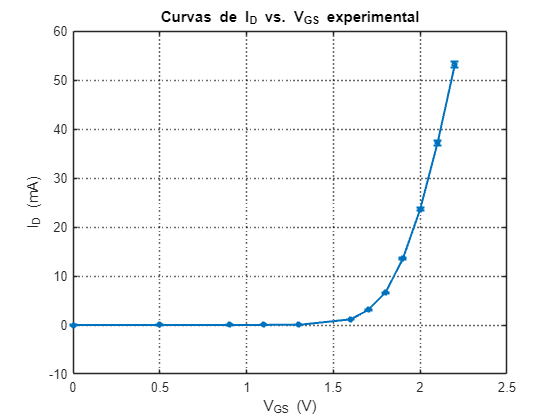

clear
% Parámetro del MOSFET (mA/V^2)
%VDD 5.95V 2n7000COA
Id_exp = [0, 0.01 , 0.02 ,  0.025 , 0.03 , 1.15 , 3.08 , 6.62 , 13.5 , 23.63 , 37.16 ,53.2 ]; %mA
Vgs_exp = [0, 0.5 , 0.9 ,  1.1 , 1.3 , 1.6 , 1.7 , 1.8 , 1.9 , 2 , 2.1 , 2.2]; %V
error_id = 0.012*Id_exp+0.02;
k = (Id_exp*2)./(Vgs_exp-1.2).^2;
figure;
errorbar(Vgs_exp, Id_exp, error_id, 'o-', 'LineWidth', 1.5, 'MarkerSize', 3); % Gráfico con barras de error
xlabel('V_{GS} (V)');
ylabel('I_D (mA)');
title('Curvas de I_D vs. V_{GS} experimental');
grid on;
% Ajusta el aspecto de la cuadrícula y los ejes
set(gca, 'GridLineStyle', ':', 'GridColor', 'k', 'GridAlpha', 0.6);
hold on;

Experimental VDS

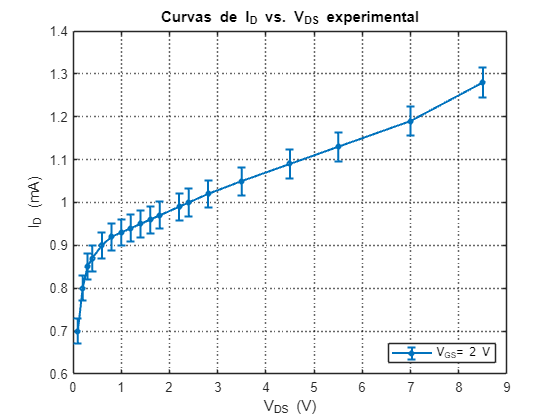

% PARA 2N7000 OTROVgs = 1.6 v
id_exp2 = [0.7, 0.8 , 0.85 , 0.87 , 0.9, 0.92 , 0.93 , 0.94 , 0.95, 0.96 , 0.97 , 0.99 , 1 , 1.02 , 1.05 , 1.09, 1.13  , 1.19, 1.28]; % mA
vds_exp2 = [0.1, 0.2 ,0.3 , 0.4 ,0.6, 0.8 , 1 , 1.2 , 1.4 , 1.6 , 1.8  , 2.2 , 2.4 , 2.8 , 3.5 , 4.5 , 5.5 , 7 , 8.5]; % V

%2N7000 CHAZA VGS = 2V
%id_exp2 = [6.68,12.31,16.1,18.51,20.1,21.16,21.88, 23.2, 23.82 , 25.84,27.1] % mA
%vds_exp2 = [0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.9,1,1.5,2] % V

error_id2 = 0.012*id_exp2+0.02;

figure;
errorbar(vds_exp2, id_exp2, error_id2, 'o-', 'LineWidth', 1.5, 'MarkerSize', 3); % Gráfico con barras de error
xlabel('V_{DS} (V)');
ylabel('I_D (mA)');
title('Curvas de I_D vs. V_{DS} experimental');
legend('V_{GS}= 2 V', 'Location', 'southeast');% Asocia la leyenda a la serie de datos
grid on;
% Ajusta el aspecto de la cuadrícula y los ejes
set(gca, 'GridLineStyle', ':', 'GridColor', 'k', 'GridAlpha', 0.6);
hold off;

Ajuste lineal vds_id

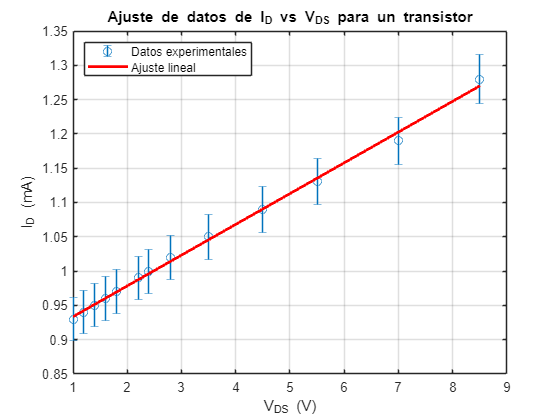

% Ajuste lineal de la forma y = p(1)*x + p(2)
% Ajuste lineal de la forma y = m*x + b
id_ajustel = id_exp2(7:end);
vds_ajustel = vds_exp2(7:end);
error_ajuste = 0.012*id_ajustel+0.02;

p = polyfit(vds_ajustel, id_ajustel, 1);
% Cálculo de los valores ajustados de Id
Id_ajustado = polyval(p, vds_ajustel);

% Gráfica de los datos y del ajuste
figure;
errorbar(vds_ajustel, id_ajustel, error_ajuste, 'o'); % Gráfica de los datos con barras de error
hold on;
plot(vds_ajustel, Id_ajustado, '-r', 'LineWidth', 2); % Gráfica del ajuste lineal
xlabel('V_{DS} (V)');
ylabel('I_{D} (mA)');
title('Ajuste de datos de I_{D} vs V_{DS} para un transistor');
legend('Datos experimentales', 'Ajuste lineal', 'Location', 'NorthWest');
grid on;


% Usar los parámetros del ajuste lineal
b = p(2) % Intersección con el eje y

b = 0.8887

m = p(1) % Pendiente de la recta

m = 0.0449


% Calcular x cuando y = 0
va = -b/ m

va = -19.8069

lambda = 1 / va

lambda = -0.0505

Ajuste cuadratico vgs_id

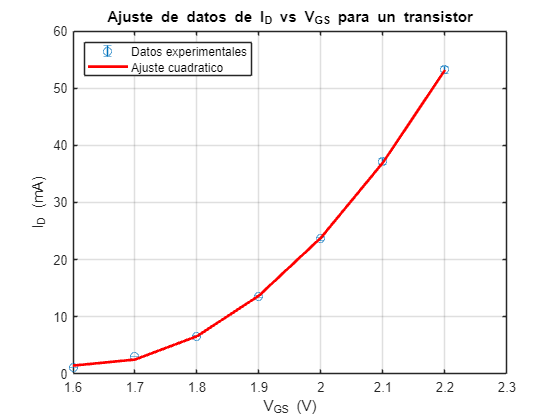

    % Ajuste cuadratico y = ax^2 + bx + c
    % Ajuste cuadratico y = p(1)*x^2 + p(2)*x + p(3)
    id_ajustec = Id_exp(6:end);
    vgs_ajustec = Vgs_exp(6:end);
    error_ajustec = 0.012*id_ajustec+0.02;
    pc = polyfit(vgs_ajustec, id_ajustec, 2);
    
    % Cálculo de los valores ajustados de Id
    Id_ajustadoc = polyval(pc, vgs_ajustec);
    
    % Gráfica de los datos y del ajuste
    figure;
    errorbar(vgs_ajustec, id_ajustec, error_ajustec, 'o'); % Gráfica de los datos con barras de error
    hold on;
    plot(vgs_ajustec, Id_ajustadoc, '-r', 'LineWidth', 2); % Gráfica del ajuste lineal
    xlabel('V_{GS} (V)');
    ylabel('I_{D} (mA)');
    title('Ajuste de datos de I_{D} vs V_{GS} para un transistor');
    legend('Datos experimentales', 'Ajuste cuadratico', 'Location', 'NorthWest');
    grid on;

    
    a=pc(1)

a = 151.1905

    b=pc(2)

b = -488.3381

    c=pc(3) 

c = 395.7600

    k = (2*a)/(1+lambda*5.95)

k = 432.2200

Ajuste 1


modelo = fittype('1000 * k/2 * (Vgs - Vth)^2', ... % *1000 para mantener la ecuacion Id = mA
                'independent', 'Vgs', ...
                'coefficients', {'k', 'Vth'});
% Valores iniciales para los coeficientes [k, Vth]
suposicion = [0.001, 0.001];  

% Realizar el ajuste usando la función fit
fit_rta = fit(vgs_ajustec', id_ajustec', modelo,'StartPoint', suposicion);

% Mostrar los resultados del ajuste
disp('Resultados del ajuste:');

Resultados del ajuste:


disp(fit_rta);

     General model:
     fit_rta(Vgs) = 1000 * k/2 * (Vgs - Vth)^2
     Coefficients (with 95% confidence bounds):
       k =       0.278  (0.2451, 0.3109)
       Vth =       1.583  (1.553, 1.613)


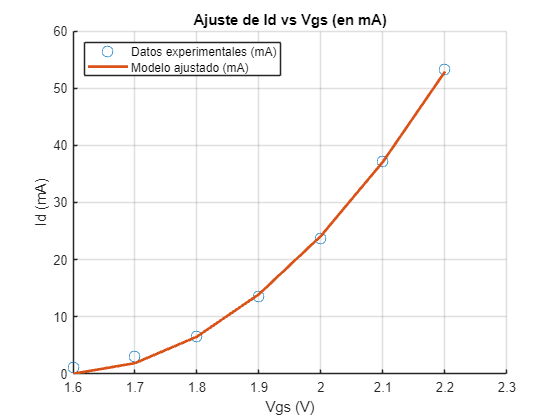


% Graficar el ajuste en mA junto con los datos experimentales en mA
figure;
hold on;
plot(vgs_ajustec, id_ajustec, 'o', 'MarkerSize', 8, 'DisplayName', 'Datos experimentales (mA)');
plot(vgs_ajustec, feval(fit_rta, vgs_ajustec), '-', 'LineWidth', 2, 'DisplayName', 'Modelo ajustado (mA)');
title('Ajuste de Id vs Vgs (en mA)');
xlabel('Vgs (V)');
ylabel('Id (mA)');
legend('show','Location', 'NorthWest');
grid on;
hold off;